# CNN for detection of hand written charecters

### Creating layers for the network

layers = [
    imageInputLayer([28 28 1],"Name","imageinput")
    convolution2dLayer([3 3],36,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([3 3],"Name","maxpool_1","Padding","same")
    convolution2dLayer([3 3],36,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([3 3],"Name","maxpool_1","Padding","same")
    convolution2dLayer([3 3],36,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    fullyConnectedLayer(56,"Name",'fc0')
    reluLayer("Name",'relu_4')
    fullyConnectedLayer(10,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
%the above network is trained for feature extraction 
%for classification of digits. we then try to classify numbers


## Training the network

We train the above network on an MNIST data set. We use the trained network to retrain the network for classification of the 36 charecters.

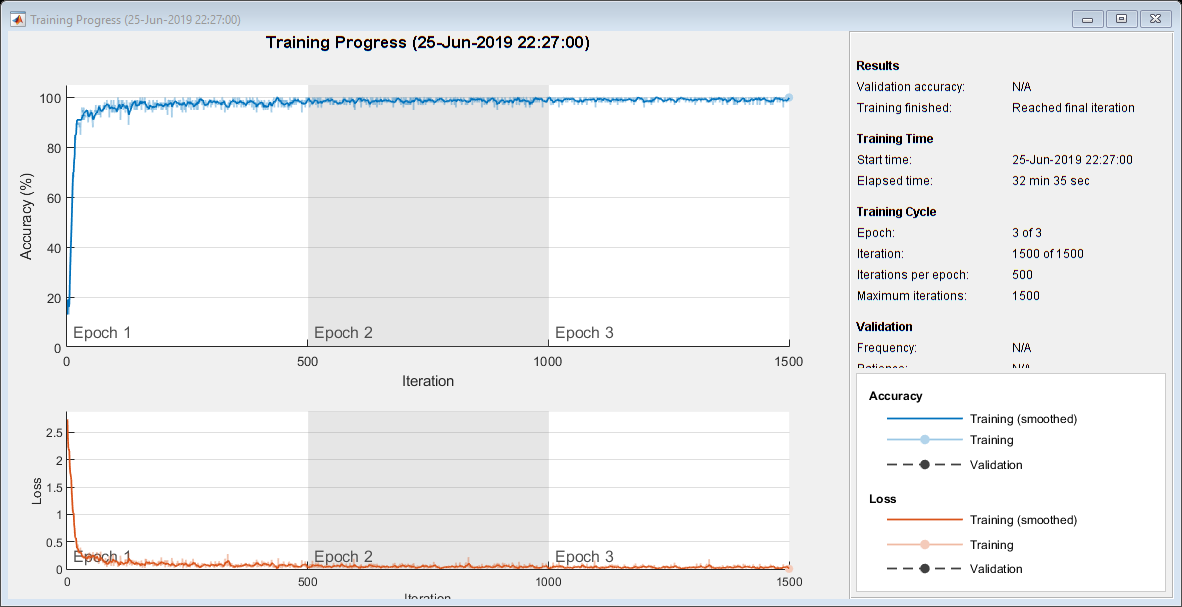

Training on single CPU.


Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |       13.00% |       2.7383 |          0.0010 |
|       1 |          50 |       00:01:18 |       94.00% |       0.2693 |          0.0010 |
|       1 |         100 |       00:02:29 |       97.00% |       0.1047 |          0.0010 |
|       1 |         150 |       00:03:40 |       98.00% |       0.0810 |          0.0010 |
|       1 |         200 |       00:05:00 |       96.00% |       0.1021 |          0.0010 |
|       1 |         250 |       00:06:10 |       97.00% |       0.0925 |          0.0010 |
|       1 |         300 |       00:07:19 |       98

%loading the MNIST datasets
mnist=load('mnist.mat');
digImds=imageDatastore('G:\digits',"IncludeSubfolders",true,"LabelSource","foldernames");
%the whole daataset is used for the training 

%setting up options for training of the network
options=trainingOptions('sgdm',...
"MaxEpochs",3,...
"MiniBatchSize",100,...
'InitialLearnRate', 0.001, ...
'LearnRateSchedule', 'piecewise', ...
'LearnRateDropFactor', 0.1, ...
'LearnRateDropPeriod', 3,...
'plots','training-progress',...
"Verbose",true...
);

%training the network for digit classification
convNet=trainNetwork(digImds,layers,options);

## Loading the images

Load the images using imageDatastore function and lable the images as their respective folder names. The images are devided into the folders with names as the lable as to what the image is.

imds=imageDatastore('C:\Users\ALOK DUBEY\Desktop\New folder\handwritten_alpha_numeric_chars',"IncludeSubfolders",true,"LabelSource","foldernames");

## Test train split of the data

The image data is split into test and training data. We will use 80% of the data for training the network and 20% data to test the performance of the network.

[train_imgs,test_images]=splitEachLabel(imds,0.9,"randomized");

## Training Options and Training the network

We set up the parameters to be used by the network for the training . We then pass the training images to the network along with the lables of the images and train the network to recognize them. We then test the network in next section and calculate it's accuracy.

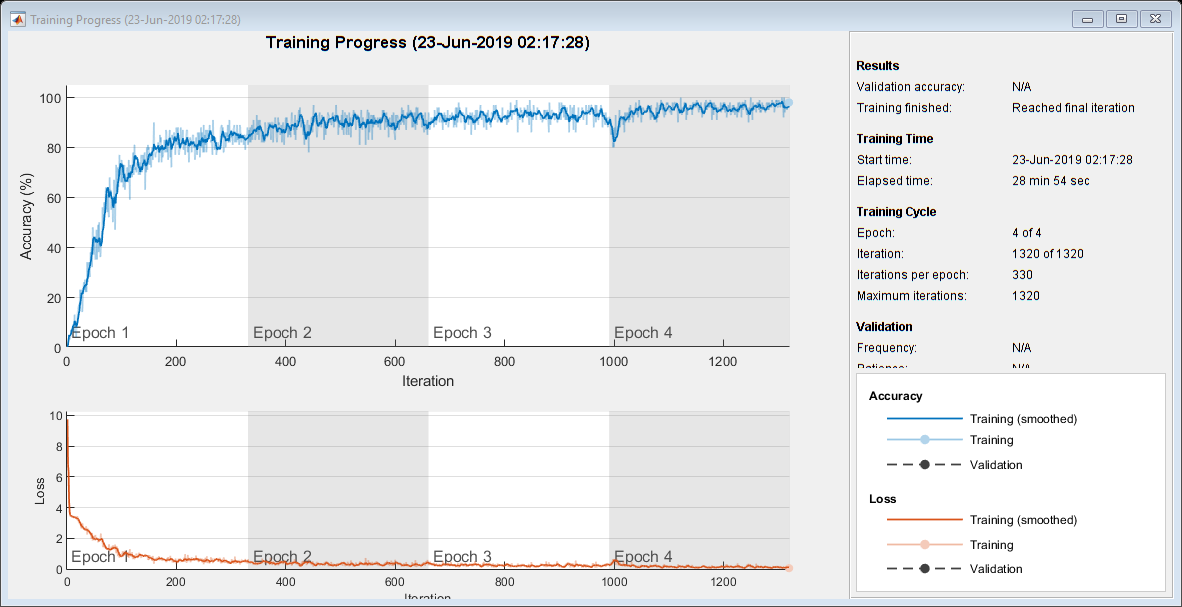

Training on single CPU.

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:09 |        0.00% |       9.7344 |          0.0100 |
|       1 |          50 |       00:01:15 |       43.00% |       1.9393 |          0.0100 |
|       1 |         100 |       00:02:22 |       75.00% |       1.0176 |          0.0100 |
|       1 |         150 |       00:03:28 |       80.00% |       0.6070 |          0.0100 |
|       1 |         200 |       00:04:35 |       88.00% |       0.3304 |          0.0100 |
|       1 |         250 |       00:05:41 |       89.00% |       0.3137 |          0.0100 |
|       1 |         300 |       00:06:47 |       87


%"MiniBatchSize",100,...\
%'InitialLearnRate', 0.001, ...
%'LearnRateSchedule', 'piecewise', ...
%'LearnRateDropFactor', 0.1, ...
%'LearnRateDropPeriod', 3,...
%"Verbose",true
layers=convNet.Layers;
layers(15)=fullyConnectedLayer(36,"Name","fc");
layers(16)=softmaxLayer();
layers(17)=classificationLayer();
opts=trainingOptions('sgdm',...
"MaxEpochs",4,...
"MiniBatchSize",100,...
'InitialLearnRate', 0.01, ...
'LearnRateSchedule', 'piecewise', ...
'LearnRateDropFactor', 0.1, ...
'LearnRateDropPeriod', 3,...
'Plots','training-progress',...
"Verbose",true...
);
%training
convNet=trainNetwork(train_imgs,layers,opts); 

%saving the trained network
save convNet;

## Evaluation of the network

We use the 20% of the images from the data for the calculation of accuray of the trained net.

%make predictions
predictedLabels=classify(convNet,test_images);
%get labels of the images in test set
y_test=test_images.Labels;
%score=number of times the prediction by the system is correct
score= sum(predictedLabels==y_test);
%accuracy is the percentage of times system makes correct prediction
accuracy=score/numel(y_test);
disp(accuracy*100);

   94.0791



## Input Image Processing

The input image is cleaned, binarized and segmented to obtain individual charecters which is then passed one by one to the convolutional nural network created above and write it out one by one to an external text file.

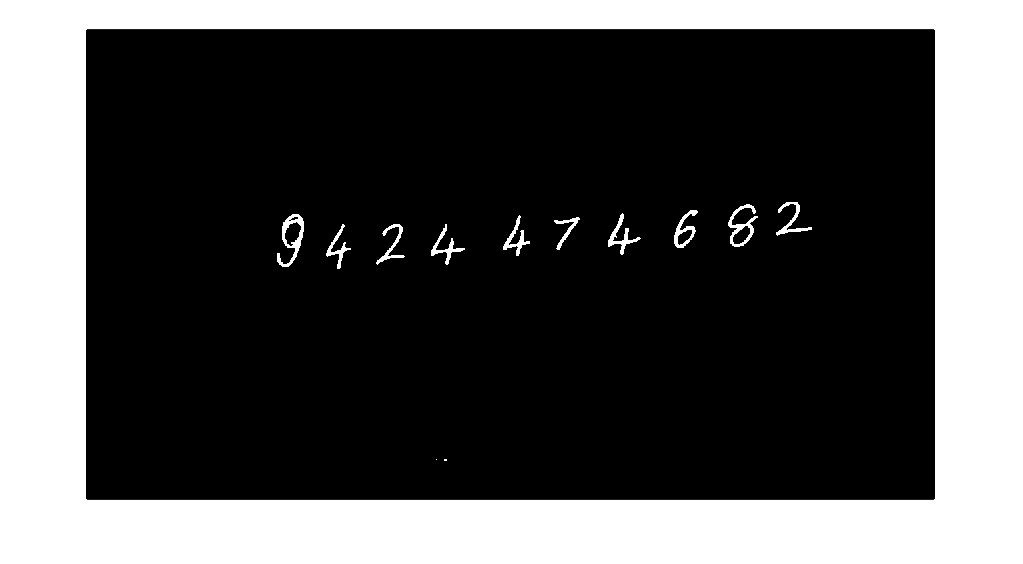

img=imread('C:\Users\ALOK DUBEY\Desktop\sample_number.jpeg');
img=rgb2gray(img);
img=medfilt2(img);
img=imbinarize(img);
img=bwlabel(img);
img=~img;
figure,imshow(img);

     5 



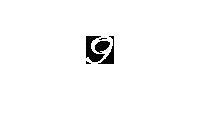

     2 



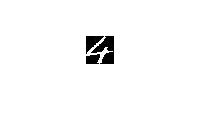

     2 



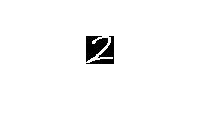

     2 



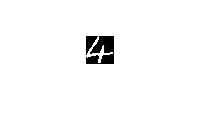

     4 



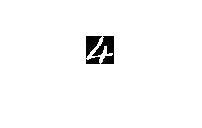

     2 



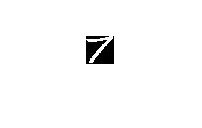

     2 



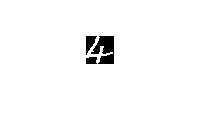

     5 



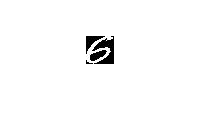

     3 



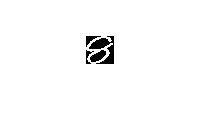

     2 



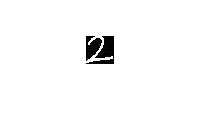

iProp=regionprops(img,'BoundingBox','Area');
for i =1:length(iProp)
    if iProp(i).Area>100
        im=imcrop(img,iProp(i).BoundingBox);
        im=imresize(im,[28 28]);
        imwrite(im,'C:\Users\ALOK DUBEY\Desktop\New folder\temp\char.jpg');
%        j=mat2gray(im);
        j=imread('C:\Users\ALOK DUBEY\Desktop\New folder\temp\char.jpg');
        ch=convNet.classify(j);
        disp(ch);
        clear ch;
        figure,imshow(j);
    end
end